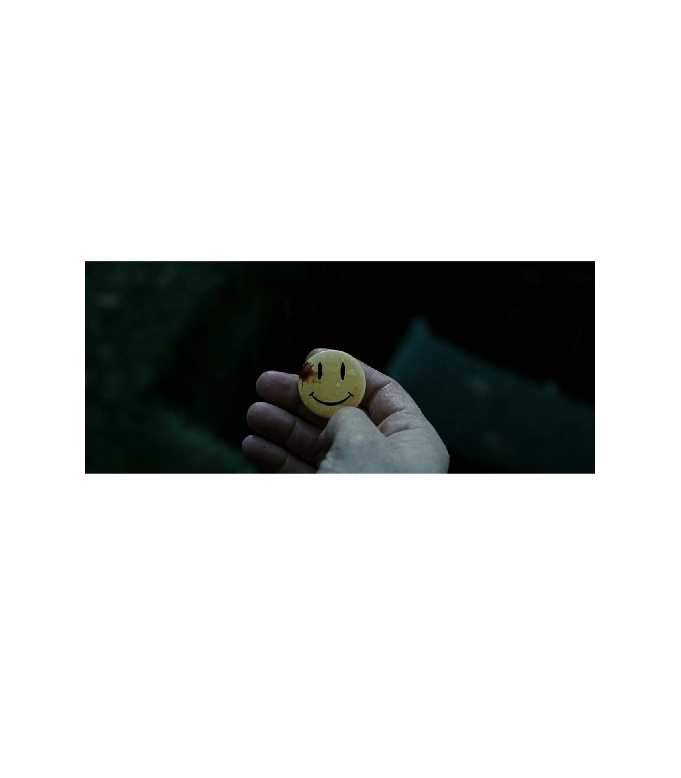

a= imread('watchmen (2).jpg');
imshow(a)

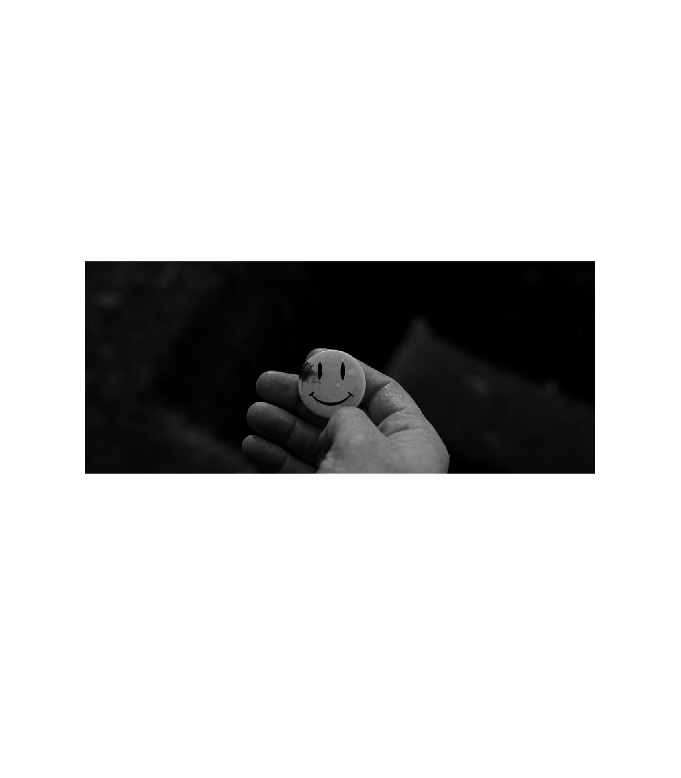

a2= im2gray(a);
imshow(a2)

corners= detectHarrisFeatures(a2)

corners =   70×1 cornerPoints array with properties:

    Location: [70×2 single]
      Metric: [70×1 single]
       Count: 70


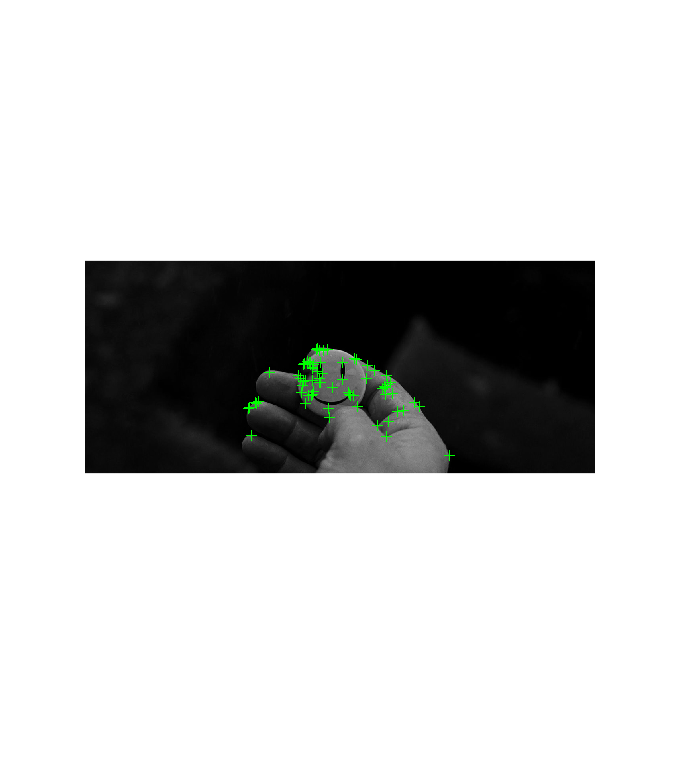

imshow(a2)
hold on
plot(corners)
hold off

imshow(a2)
hold on
strong_corners= selectStrongest(corners,40)

strong_corners =   40×1 cornerPoints array with properties:

    Location: [40×2 single]
      Metric: [40×1 single]
       Count: 40


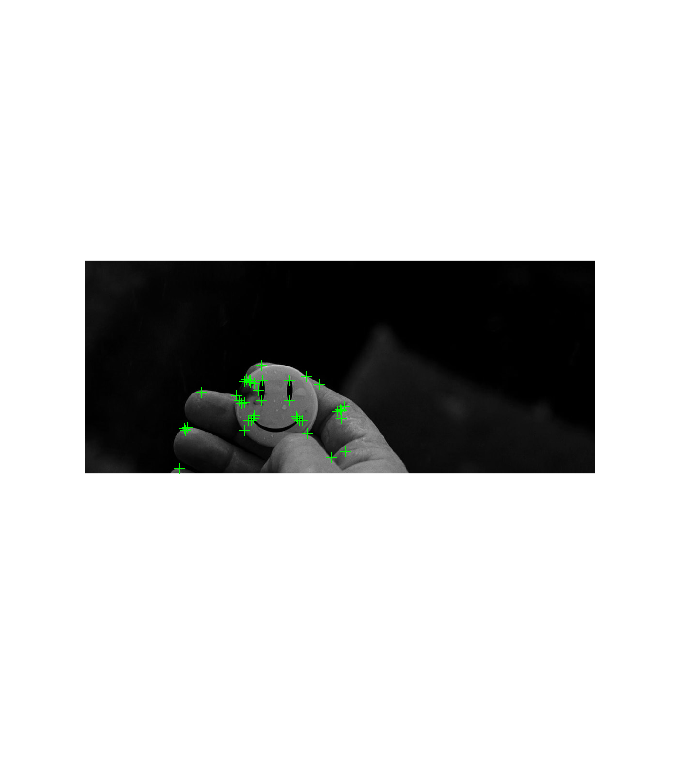

plot(strong_corners)
hold off

points= detectSURFFeatures(a2)

points =   59×1 SURFPoints array with properties:

              Scale: [59×1 single]
    SignOfLaplacian: [59×1 int8]
        Orientation: [59×1 single]
           Location: [59×2 single]
             Metric: [59×1 single]
              Count: 59


imshow(a2)
hold on
strong_points= selectStrongest(points,100)

strong_points =   59×1 SURFPoints array with properties:

              Scale: [59×1 single]
    SignOfLaplacian: [59×1 int8]
        Orientation: [59×1 single]
           Location: [59×2 single]
             Metric: [59×1 single]
              Count: 59


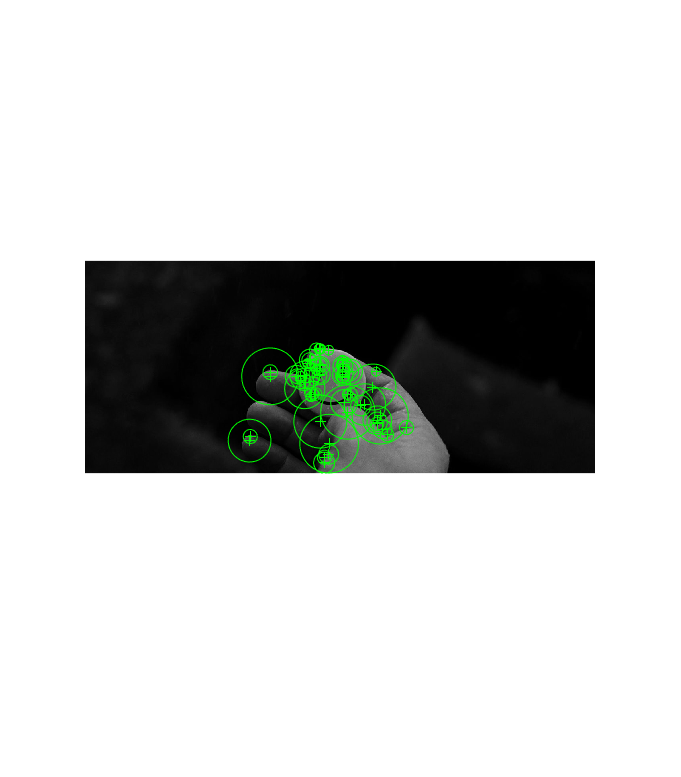

plot(strong_points)
hold off

regions = detectMSERFeatures(a2)

regions =   44×1 MSERRegions array with properties:

          Count: 44
       Location: [44×2 single]
           Axes: [44×2 single]
    Orientation: [44×1 single]
      PixelList: {44×1 cell}


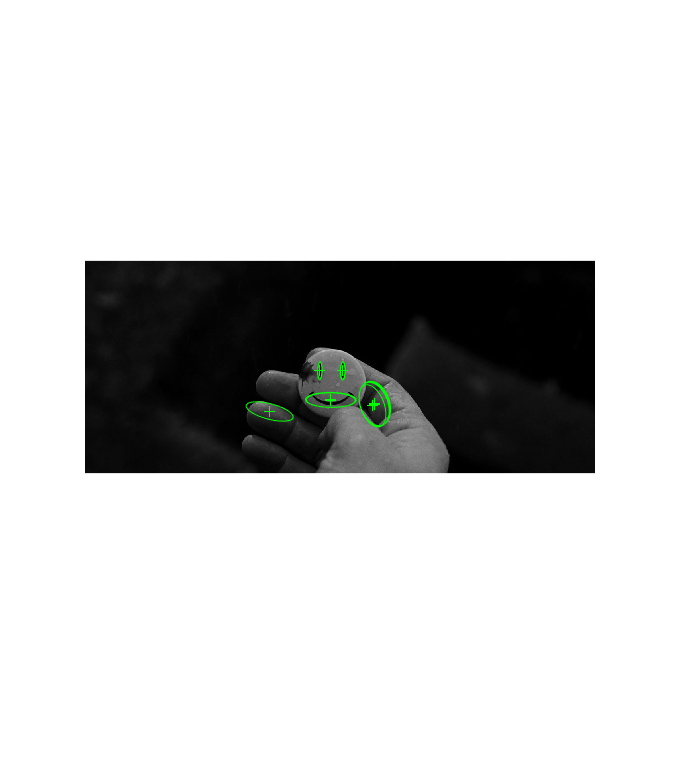

imshow(a2)
hold on
plot(regions)
hold off